*Copyright (c) 2024 by Central South University.*

`coding: utf-8`

## Test the time the function runs.

*Programme written by Y. Yang*

*For more information, contact by email: <yangyaokun@csu.edu.cn>.*

Please read the README.md before use.

clearvars

model = [-50,50,-50,50,-150,-50,2000];
area = ObservationPlane(model);

## test the cost time

历时 0.767699 秒。
历时 0.650340 秒。
历时 1.046963 秒。
历时 1.664033 秒。
历时 2.575206 秒。
历时 1.911593 秒。
历时 2.320990 秒。
历时 2.769156 秒。
历时 3.396264 秒。
历时 3.997903 秒。
历时 4.786008 秒。
历时 5.804798 秒。
历时 6.866087 秒。
历时 8.083831 秒。
历时 9.429589 秒。
历时 10.959092 秒。
历时 12.279899 秒。


## plot the cost time

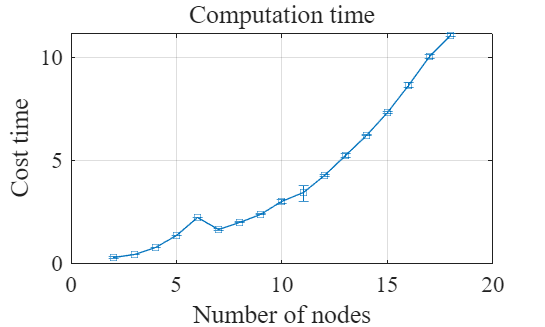

load Data\CostTimeofGaussianQuad.mat

n = t(:,1);
t = t(:,2:5);

cv = mean(t,2);
pos = max(t,[],2) - cv;
neg = min(t,[],2) - cv;

figure
errorbar(n,cv,neg,pos,'-s','MarkerSize',5)
grid on
xlabel('Number of nodes')
ylabel('Cost time')
title('Computation time')
ax = gca;
ax.FontName = 'Times New Roman';
ax.FontSize = 14;